**Item a y b del ej 3 resuelto en papel**

**C)**

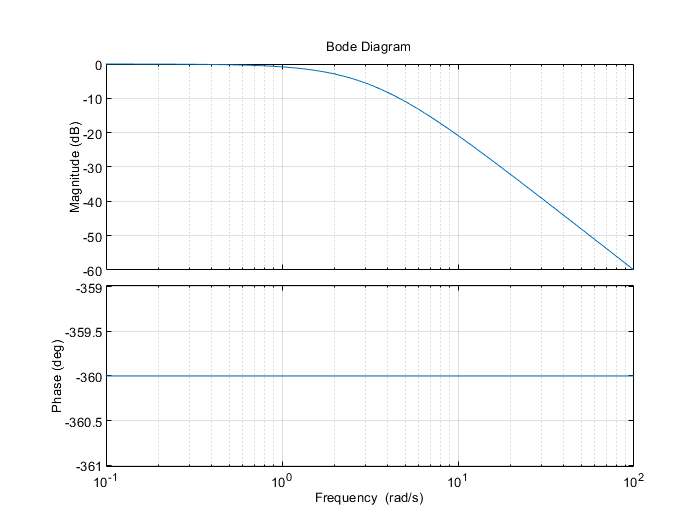


close all
clear all
clc


% Config:
s = tf('s');

optionss=bodeoptions;
optionss.MagVisible='on';
optionss.PhaseMatching='on';
optionss.PhaseMatchingValue=-180;
optionss.PhaseMatchingFreq=1;
optionss.Grid='on';

%constantes
g = 10;
m = 0.1;

%variables de estado
orden = 2;
x=sym('x',[orden 1],'real');
u=sym('u','real');

% Punto de equlibrio 
u_e = 1;
x_e = [1 ; 0];

%f es mi X_punto
f1 = x(2);
f2 = g-u/(x(1)*m);

f = [f1;f2];

%g es mi salida 
g = x(1);

A = jacobian(f,x);
A = double(subs(A,{x(1),x(2),u},{x_e(1),x_e(2),u_e}));

B = jacobian(f,u);
B = double(subs(B,{x(1),x(2),u},{x_e(1),x_e(2),u_e}));

C = jacobian(g,x);
C = double(subs(C,{x(1),x(2),u},{x_e(1),x_e(2),u_e}));

D = jacobian(g,u);
D = double(subs(D,{x(1),x(2),u},{x_e(1),x_e(2),u_e}));

% Transferencia de la Planta Linealizada
P = tf(ss(A,B,C,D));


figure(); 
bode(P,optionss);

Si observamos el pzmap, tenemos un polo en raíz de 10 y otro en -raíz de 10. Por lo tanto, al tener un polo en el SPD, decimos que la planta es inestable. 

**Item E)**

Primero divido a la planta en pmp y pap

%P=-10/(s-raiz10)(s+raiz10)

pmp = (-10)/((s + 3.1623)*(s + 3.1623));

pap = (s + 3.1623)/(s - 3.1623);

% figure()
% bode(pap, optionss)

Luego, agrego el controlador integral y un polo alejado para gaarntizar que el numerador del controlador no sea mayor al del denominador y observo el root locus:

% rlocus(1*P/(pmp*s*(s+200)))

Se observa que para un valor de k >= 700, se me estabilizan los polos del semiplano derecho. 

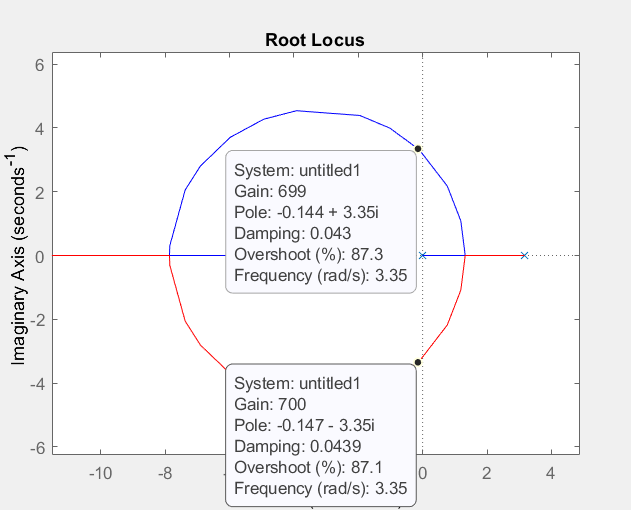

Luego, mi controlador sería el siguiente: 

k = 1;
c = k/(pmp*s*(s+200));
%bode(c*P, optionss);


En el diagrama de bode, se observa que para garantizar un MF=65 (que luego restaré 5 grados debido al sampleo de la (ecuación A), debo agregar 71.2dB a la gannacia

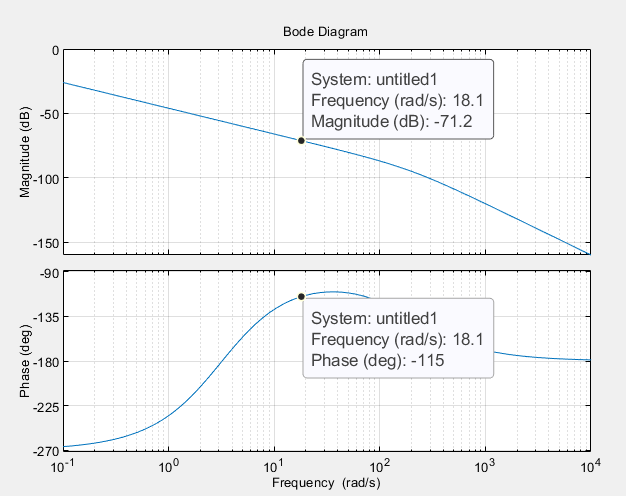

k = db2mag(71.2)

k = 3.6308e+03

c = k/(pmp*s*(s+200));
%bode(c*P, optionss);

Ahora resta calcular el valor de T de (Ec. A) tal que me reste 5 grados de MF. Se iteran varios valores:

% T = [0.1 0.22 0.01 0.0075 0.005 0.004 0.003 0.002 0.001];
% 
% 
% figure()
% bode(c*P, optionss, 'black');
% grid on
% hold on
% for i=1:length(T)
%     T(i)
%     Pad=(1-T(i)/4*s)/(1+T(i)/4*s);
%     bode(c*P*Pad, optionss)
% end
% 
% legend('L', '0.1', '0.22',' 0.01 ', '0.0075','0.005 ','0.004 ','0.003 ','0.002 ','0.001')
% hold off

Se puede notar que para T = 0,01 se cumple con el MF necesario. 

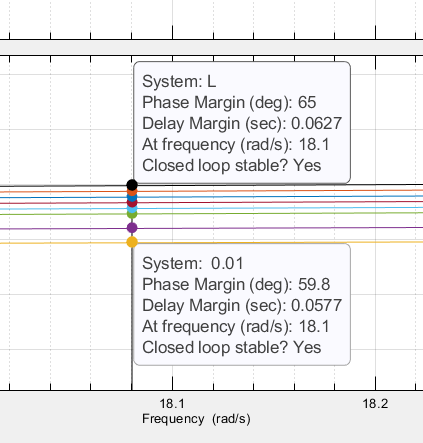

Finalmente, la planta queda de la siguiente manera:

pade_final = (1-0.01/4*s)/(1+0.01/4*s);
L = c*P*pade_final;
% bode(L, optionss)

Se puede notar que el margen de fase es el pedido:

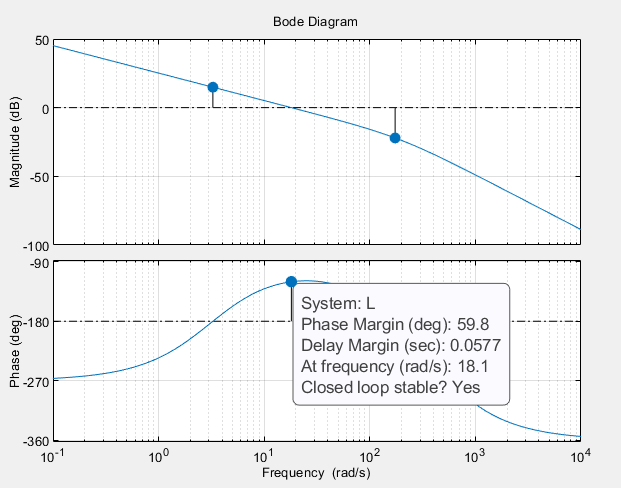

Grafico el grupo de las 4: 

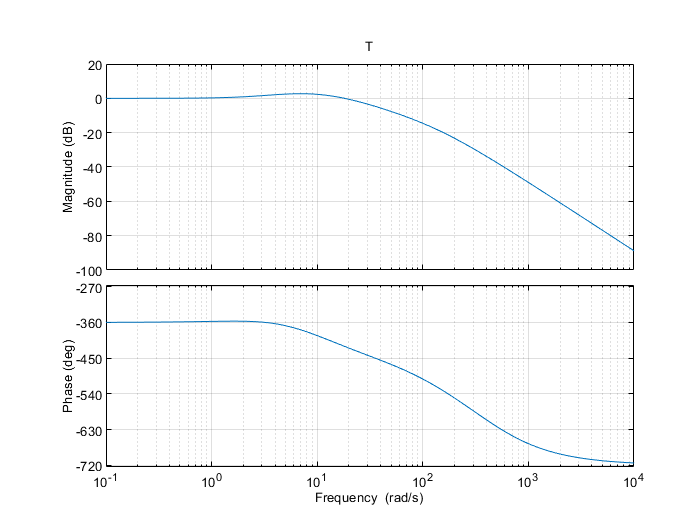

T_transf = minreal(L/(1+L)); 
figure() 
bode(T_transf,optionss);title('T');

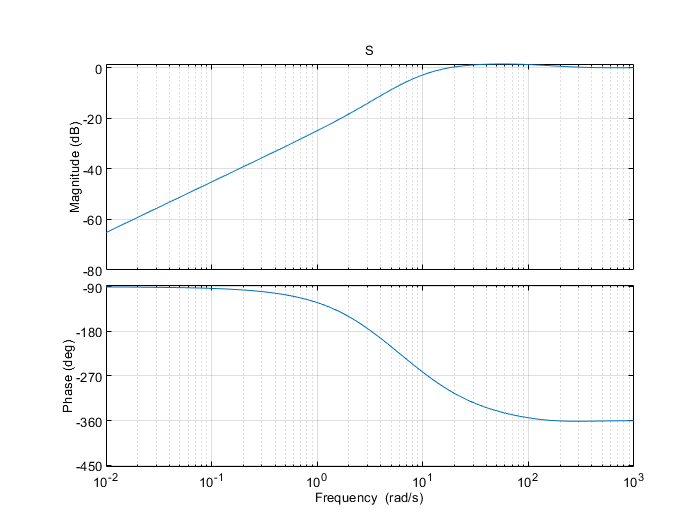

S_transf = 1 - T_transf;  
figure()
bode(S_transf,optionss);title('S');

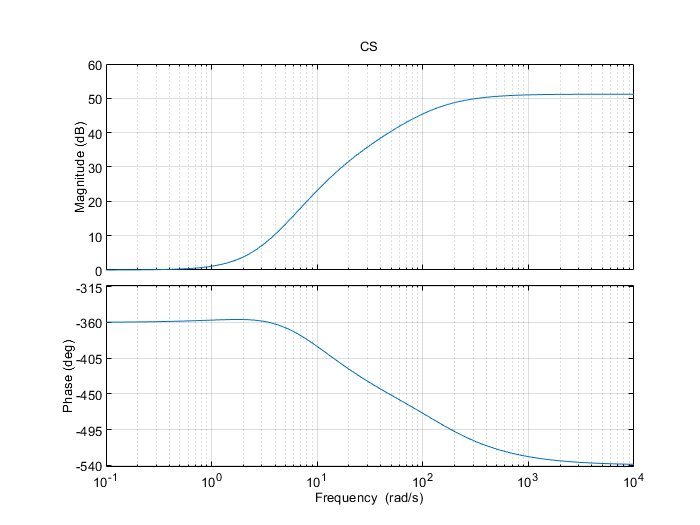

CS = minreal(c*S_transf); 
figure()
bode(CS,optionss);title('CS');

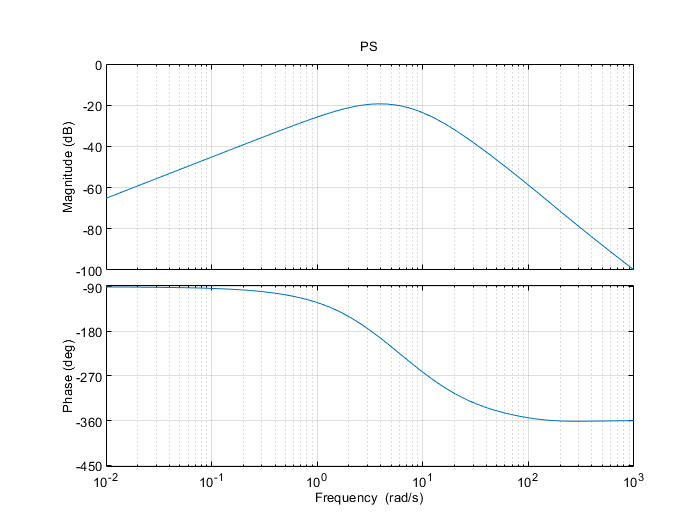

PS = minreal(P*S_transf);
figure()
bode(PS,optionss);title('PS');

Ahora grafico la respuesta al escalón:

*Respuesta al escalón*

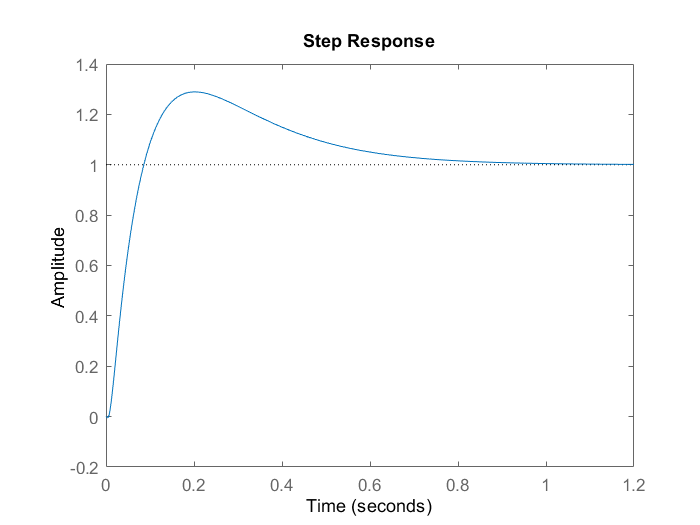

figure()
step(T_transf);

Se nota que el sobrepico es mayor al pedido. Por lo tanto, si se aumenta el "k" al doble:

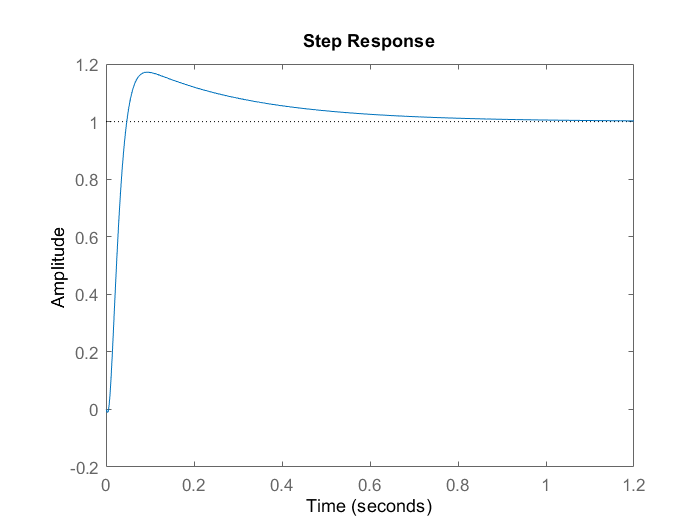

figure();
step(feedback(2*L,1))

Se aproxima mucho mejor a lo pedido. Ademas, se corrobora en el diagrama de bode que el MF siguie siendo 60°.

% bode(2*L, optionss)

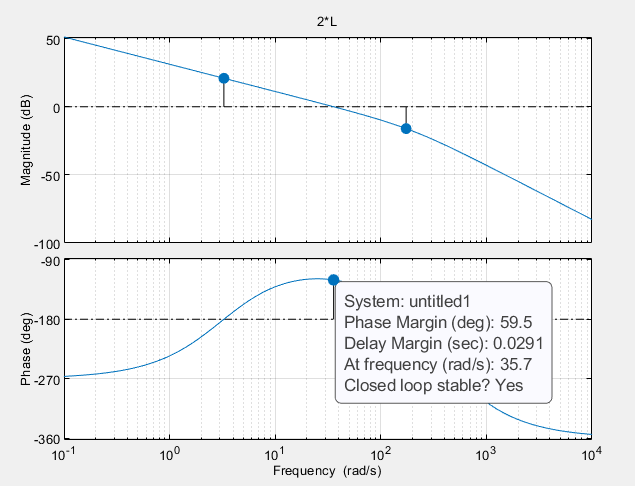

Para calcular el márgen de estabilidad, basta con graficar el diagrama de bode de S y observar su valor máximo en el diagrama de magnitud. 

% S_transf = 1 - T_transf;  
% figure()
% bode(S_transf,optionss);title('S');

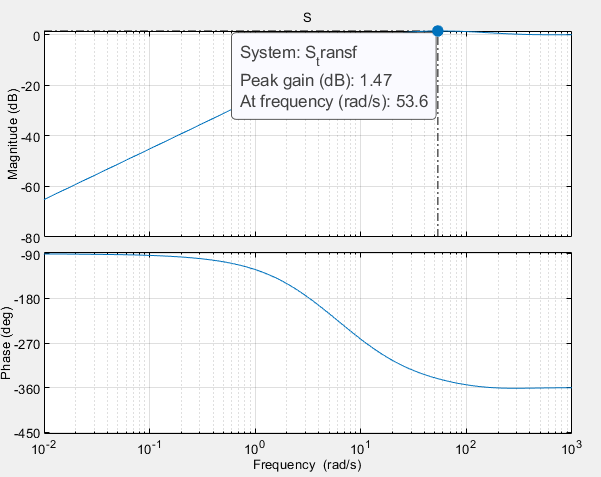

Se nota que el valor máximo es de 1,47dB. El margen de estabilidad se calcula como 1/sobrepico.

s_m = 1/db2mag(1.47)

s_m = 0.8443

Esto da como resultado un margen de estabilidad s_m = 0.8443

*Ejercicio 3*

Luego de diseñar el controlador para la planta linealizada, ahora coloco dicho controlador en el simulink para hacer la simulación no lineal completa. Si se observa el Scope:

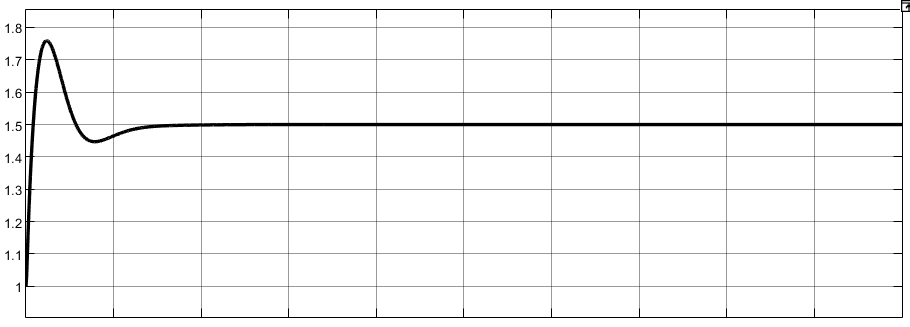

Se puede notar que arranca desde el punto de equilibro (1), y luego se estabiliza en 1.5, que es el punto de equilibrio + 0.5, que es el valor constante del escalón.